## (Self note) mpc_2.mlx differs from mpc.mlx by allowing floating x and y in our trajectories. We're still using rounded x and y with lookup table instead of using interpolation

clear all;
clc;
clf;

## Elevation, Soil, and Visibility data

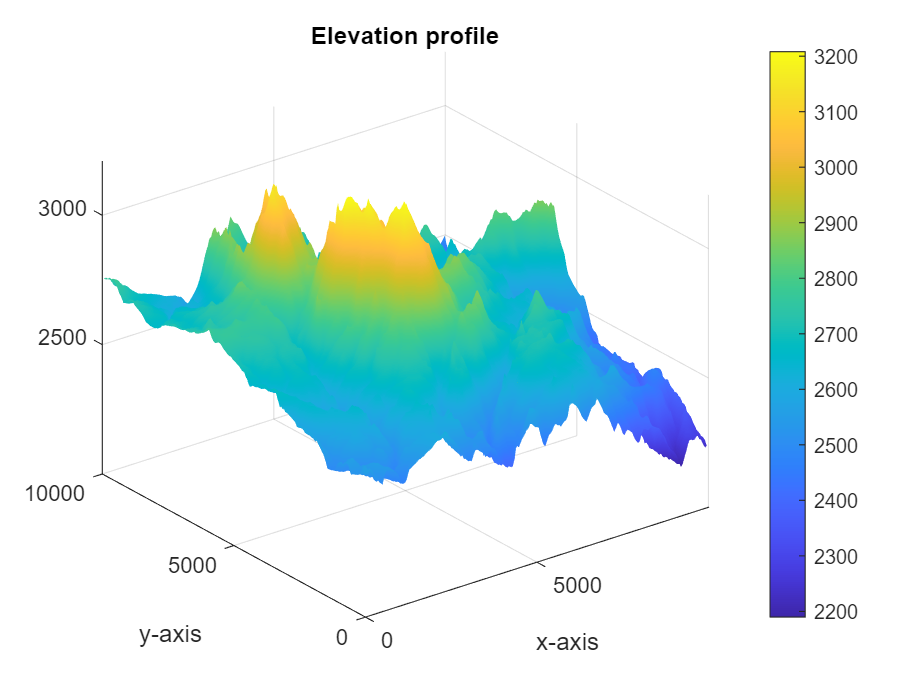

global x_min x_max y_min y_max;

ZM = load('map.txt');
soil = load('soil.txt');
vis = load('visibility.txt');

xv = [0:50:50*(size(ZM,2)-1)];
XM = zeros(size(ZM,2));
for i=1:size(ZM,2)
    XM(i,:) = xv;
end

yv = [0:50:50*(size(ZM,1)-1)]';
YM = zeros(size(ZM,1));
for i=1:size(ZM,1)
    YM(:,i) = yv;
end

clear xv yv i;

% Finding min/max for x & y
x_min = min(min(XM));       % This was very computationally expensive if done within the cost function
x_max = max(max(XM));
y_min = min(min(YM));
y_max = max(max(YM));

figure(1);
surf(XM, YM, ZM);
title("Elevation profile");
shading interp;
cb = colorbar('Location', 'eastoutside');
xticks([0,5000]);
zticks([2500,3000]);
xlabel("x-axis");
ylabel("y-axis");

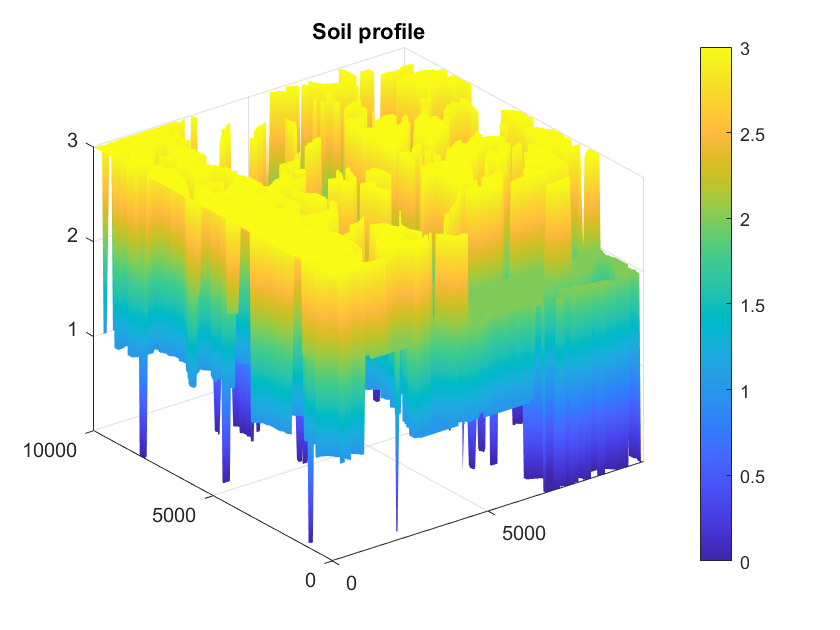

figure(2);
surf(XM,YM,soil);
title("Soil profile");
shading interp;
colorbar;
xticks([0,5000]);
zticks([1,2,3]);

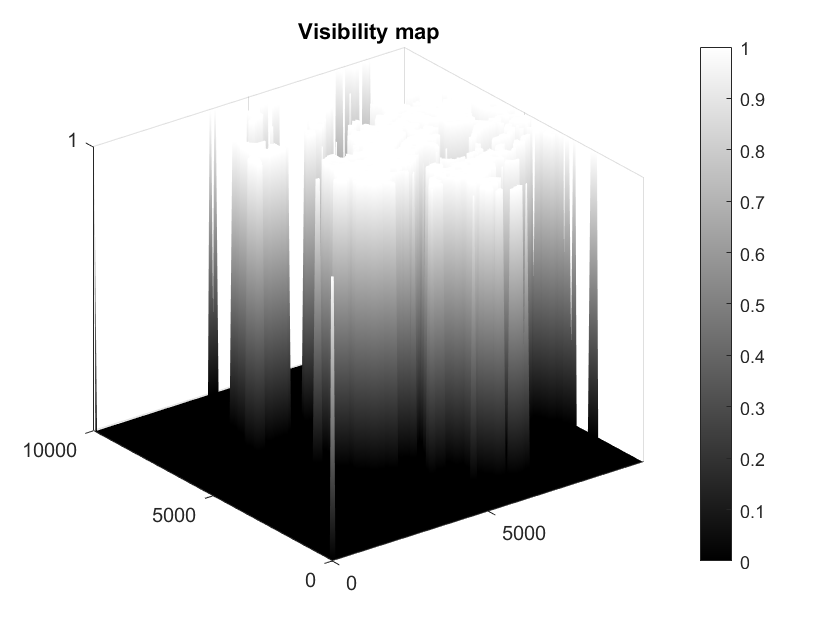

figure(3);
surf(XM,YM,vis);
title("Visibility map");
shading interp;
colormap gray;
colorbar;
xticks([0,5000]);
zticks([1]);

## High Resolution Data (Interpolated)

%% X and Y matrices with 1 meter intervals
global Xm Ym;

xv = [0:1:9950];
Xm = zeros(length(xv)); % high resolution x
for i=1:length(xv)
    Xm(i,:) = xv;
end

yv = [0:1:9950]';
Ym = zeros(length(yv)); % high resolution y
for i=1:length(yv)
    Ym(:,i) = yv;
end

clear xv yv i;

% High-res Elevation data
global Zm;
Zm = interp2(XM, YM, ZM, Xm, Ym); % high resolution z

% High-res soil data
global soilm;
soilm = interp2(XM, YM, soil, Xm, Ym); % high resolution soil map
soilm = round(soilm);       % Important: Round off the values to match the rating system

% High-res visibility data
global vism;
vism = interp2(XM, YM, vis, Xm, Ym); % high resolution visibility map
vism = round(vism);         % Important: Round off the values to match the rating system

## Obstacle Map (Assumed)

global obsm;
obsm = zeros(size(Zm));
obsm(1619,3199) = 1;
obsm(4178,6650) = 1;

## Dynamic Programming

% Weights
w1_dp = 2;     % distance
w2_dp = 7.5;     % soil
w3_dp = 10;     % elevation
w4_dp = 50;     % visibility
max_slope = 0.3;    % 30 percent slope

% Vector storing whether vertex included in shortest path set
incl = zeros(size(YM,1)*size(XM,2), 1);

% Vector storing (*not yet optimal) cost-to-go for each vertex as DP progresses
cost = inf*ones(size(incl));
cost(sub2ind(size(ZM),200,200)) = 0;

tic
% Run Dijkstra till each vertex is included in the shortest path set
while length(incl(incl == 0)) ~= 0
    % Find non-included vertex with min cost-to-go and mark it as included
    cost_temp = cost;
    cost_temp((incl == 1)) = NaN;
    [minV_cost,minV_i] = min(cost_temp);
    incl(minV_i) = 1;

    % Find (x,y) index in Zm for the included vertex
    [r,c] = ind2sub(size(ZM),[minV_i]);

    % Find (x,y) subscript index for adjacent 8 vertices and filter out-of-bound
    % indices
    adj_s = [r-1, c-1;
        r, c-1;
        r+1, c-1;
        r-1, c;
        r+1, c;
        r-1, c+1;
        r, c+1;
        r+1, c+1];
    impos_r = (adj_s(:,1) < 1) | (adj_s(:,1) > 200);
    impos_c = (adj_s(:,2) < 1) | (adj_s(:,2) > 200);
    impos = (impos_r | impos_c);
    adj_s = adj_s((impos ~= 1),:);

    % Find the linear indices for adj_s
    adj_i = sub2ind(size(ZM), adj_s(:,1), adj_s(:,2));

    % Find (x,y,z) coordinates for included vertex
    minV_x = XM(r,c);
    minV_y = YM(r,c);
    minV_z = ZM(r,c);

    % Find (x,y,z) coordinates for adjacent vertices
    adj_x = XM(sub2ind(size(XM),adj_s(:,1), adj_s(:,2)));
    adj_y = YM(sub2ind(size(YM),adj_s(:,1), adj_s(:,2)));
    adj_z = ZM(sub2ind(size(ZM),adj_s(:,1), adj_s(:,2)));

    % Calculate each adjacent vertex's (*not yet optimal) cost-to-go to
    % the vertex included in the beginning of this iteration
    J_dist = sqrt((minV_x - adj_x).^2 + (minV_y - adj_y).^2 + (minV_z - adj_z).^2);
    J_soil = 1./soil(r,c) + 1./soil(sub2ind(size(soil), adj_s(:,1), adj_s(:,2)));
    J_elev = abs(minV_z - adj_z);
    slope = abs(J_elev./sqrt((minV_x - adj_x).^2 + (minV_y - adj_y).^2));
    J_elev(slope >= max_slope) = inf;
    J_vis = vis(r,c)*ones(size(J_elev));
    J = w1_dp*J_dist + w2_dp*J_soil + w3_dp*J_elev + w4_dp*J_vis;

    % Update costs for adjacent vertices if J < cost
    cost(adj_i) = min(cost(adj_i), minV_cost + J);
end

% Optimal cost-to-go at each point
costDP = reshape(cost, [200,200]);

toc

Elapsed time is 7.062873 seconds.


## Visualize Cost Map

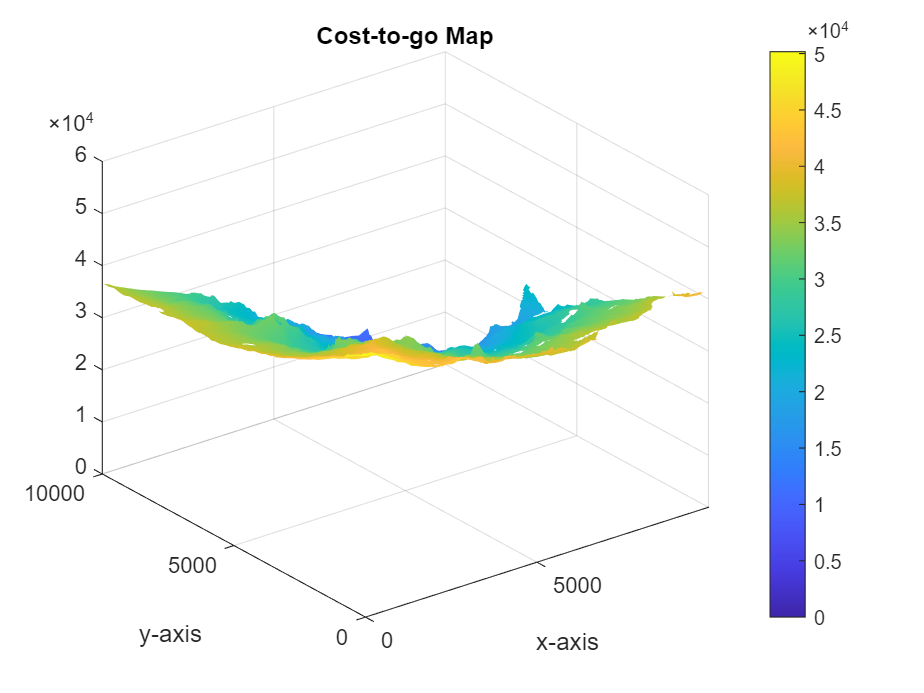

%clf(4)
figure(4);
surf(XM, YM, costDP);
title("Cost-to-go Map");
%caxis([0, 5e4]);
shading interp;
set(gca,'xtick',[0,5000]);
set(gca,'ytick',[0,5000,10000]);
xlabel("x-axis");
ylabel("y-axis");
colorbar;

## Visualize DP Recommended Global Path

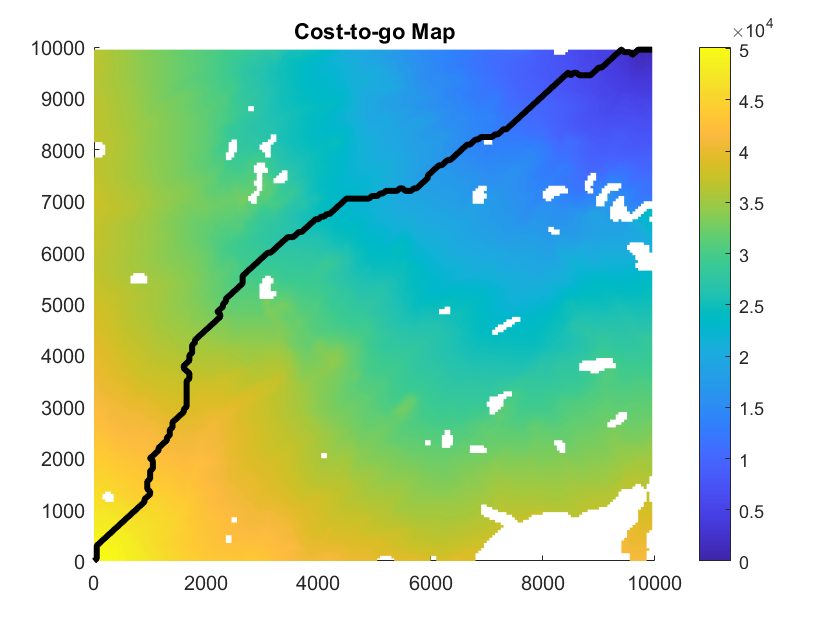

x_recDP = zeros(10*size(costDP,2),1);
y_recDP = zeros(10*size(costDP,1),1);
recDPsteps = 0;

r = x_min+1;
c = y_min+1;

while (r ~= size(costDP,1)) || (c ~= size(costDP,2))
    % Find adjacent 8 vertices and filter out-of-bound indices
    adj_s = [r-1, c-1;
        r, c-1;
        r+1, c-1;
        r-1, c;
        r+1, c;
        r-1, c+1;
        r, c+1;
        r+1, c+1];
    impos_r = (adj_s(:,1) < 1) | (adj_s(:,1) > 200);
    impos_c = (adj_s(:,2) < 1) | (adj_s(:,2) > 200);
    impos = (impos_r | impos_c);
    adj_s = adj_s((impos ~= 1),:);

    [~,I] = min(costDP(sub2ind(size(costDP), adj_s(:,1), adj_s(:,2))));
    r = adj_s(I,1);
    c = adj_s(I,2);
    recDPsteps = recDPsteps + 1;

    x_recDP(recDPsteps+1) = XM(1,c);
    y_recDP(recDPsteps+1) = YM(r,1);
end

clf;
figure(5);
hold on;
surf(XM, YM, costDP);
plot3(x_recDP(1:recDPsteps+1), y_recDP(1:recDPsteps+1), 1e5*ones(recDPsteps+1,1), 'k', 'LineWidth',3);
title("Cost-to-go Map");
shading interp;
colorbar;
hold off;

## High Resolution DP cost-to-go (Interpolated)

global costDPm;
costDPm = interp2(XM, YM, costDP, Xm, Ym);

clear incl cost cost_temp;
clear minV_cost minV_i minV_x minV_y minV_z r c;
clear adj_s adj_i adj_x adj_y adj_z impos impos_r impos_c;
clear J J_dist J_soil J_elev J_vis;

## MPC Parameters

%%%%%%%%%%%%%% MPC parameters %%%%%%%%%%%%%%
global Np;
global w1 w2 w3 w4 w5;  % Individual cost weights

% Prediction horizon
Np = 25;    

% Cost weights
w1 = w1_dp;
w2 = w2_dp;
w3 = w3_dp;
w4 = 0;
w5 = w4_dp;

% Input constraint limits
delta_max = (pi/3);
delta_dot_max = delta_max/0.15;

% fmincon options
optionDisp = optimoptions('fmincon');
optionNoDisp = optimoptions('fmincon','Display','off');

% Warning settings
warning("off", "all");

## MPC Input Constraints (A*x <= B)

%%%%%%%%%%%%%% Inequality constraint matrix A %%%%%%%%%%%%%%
A = zeros(2*(Np-1)+2*(Np-2), Np);
% Constraints on max delta
for i=1:(Np-1)
    A(i,i) = -1;
    A(i,i+1) = 1;
end
for i=Np:2*(Np-1)
    A(i,i-Np+1) = 1;
    A(i,i-Np+2) = -1;
end
% Constraints on max delta_rate
for i=2*(Np-1)+1:2*(Np-1)+(Np-2)
    A(i,i-2*(Np-1)+2) = 1;
    A(i,i-2*(Np-1)+1) = -2;
    A(i,i-2*(Np-1)) = 1;
end
for i=2*(Np-1)+(Np-2)+1:size(A,1)
    A(i,i-(3*Np-4)+2) = -1;
    A(i,i-(3*Np-4)+1) = 2;
    A(i,i-(3*Np-4)) = -1;
end

%%%%%%%%%%%%%% Inequality constraint matrix B (delta max/ max steering input) %%%%%%%%%%%%%%
B = ones(2*(Np-1)+2*(Np-2),1);
B(1:2*(Np-1)) = delta_max;
B(2*Np-1:end) = delta_dot_max;

## Model Predictive Controller

%%%%%%%%%%%%%% Running MPC for the whole journey %%%%%%%%%%%%%%
% Storing control history
u_opt = zeros(10*size(Xm,1),1);   % Declaring extra large vector because we don't know number of control inputs required
global num_u;
num_u = 0;  % will update from loop

% Storing optimal state trajectory
x_traj = zeros(size(u_opt));
y_traj = zeros(size(u_opt));

% Starting at (0,0)
global x_start y_start x_end y_end;
x_start = Xm(1,1);
y_start = Ym(1,1);

tic
while ((x_start <= x_max - Np) || (y_start <= y_max - Np)) && (num_u <= 18700)
    % Possible delta_s, x and y
    pos_u = [0: pi/180: 359*pi/180];    % possible heading angles in radians
    pos_xN = x_start + Np*cos(pos_u);   % Np is the radius at Nth step
    pos_yN = y_start + Np*sin(pos_u);

    %% Filter out out-of-bound x & y
    % Finding indices of infeasible x and y
    notpos_xN_ind = (pos_xN < x_min) | (pos_xN > x_max);
    notpos_yN_ind = (pos_yN < y_min) | (pos_yN > y_max);
    % Assigning NaN to x values based on infeasible x & y indices
    pos_xN(notpos_xN_ind) = NaN;
    pos_xN(notpos_yN_ind) = NaN;
    % Assigning NaN to y values based on infeasible x & y indices
    pos_yN(notpos_xN_ind) = NaN;
    pos_yN(notpos_yN_ind) = NaN;
    % Removing NaN pairs from the vectors representing possible x & y pairs 
    pos_xN = pos_xN(~isnan(pos_xN));
    pos_yN = pos_yN(~isnan(pos_yN));
    % Find (xN, yN) pair with minimum cost-to-go
    [minCost, I] = min(costDPm(sub2ind(size(costDPm), round(pos_xN)+1, round(pos_yN)+1))); % Assuming cost-to-go at (32.28, 43.31) should be very close to that at (32,43)
    x_end = pos_xN(I);
    y_end = pos_yN(I);
  
    %% Run fmincon for this kth step
    u_init = atan((y_end - y_start)/(x_end - x_start)); % Calculating initial u for faster fmincon convergence
    u_cal = fmincon(@mpcCostFunction, u_init*ones(Np,1), A, B, [], [], [], [], [], optionNoDisp);
    num_u = num_u + 1;
    u_opt(num_u) = u_cal(1);

    % Update x_start and y_start
    x_start = x_start + 1*cos(u_opt(num_u));    % delta_s for the 1st step is equal to r = 1 meter
    y_start = y_start + 1*sin(u_opt(num_u));

    % Saving trajectory for later visualization
    x_traj(num_u+1) = x_start;
    y_traj(num_u+1) = y_start;

    if (mod(num_u,500) == 0)
        toc
        fprintf("num_u = %d\n", num_u);
        tic
    end
end

Elapsed time is 2.207514 seconds.


num_u = 500


Elapsed time is 2.044741 seconds.


num_u = 1000


Elapsed time is 2.132157 seconds.


num_u = 1500


Elapsed time is 1.757550 seconds.


num_u = 2000


Elapsed time is 1.752160 seconds.


num_u = 2500


Elapsed time is 2.262666 seconds.


num_u = 3000


Elapsed time is 2.222099 seconds.


num_u = 3500


Elapsed time is 2.153134 seconds.


num_u = 4000


Elapsed time is 1.994569 seconds.


num_u = 4500


Elapsed time is 1.894802 seconds.


num_u = 5000


Elapsed time is 2.047848 seconds.


num_u = 5500


Elapsed time is 1.625868 seconds.


num_u = 6000


Elapsed time is 1.590310 seconds.


num_u = 6500


Elapsed time is 1.629424 seconds.


num_u = 7000


Elapsed time is 1.601794 seconds.


num_u = 7500


Elapsed time is 1.614334 seconds.


num_u = 8000


Elapsed time is 1.605984 seconds.


num_u = 8500


Elapsed time is 1.605024 seconds.


num_u = 9000


Elapsed time is 1.632201 seconds.


num_u = 9500


Elapsed time is 2.022792 seconds.


num_u = 10000


Elapsed time is 2.026786 seconds.


num_u = 10500


Elapsed time is 1.909066 seconds.


num_u = 11000


Elapsed time is 1.678486 seconds.


num_u = 11500


Elapsed time is 1.600399 seconds.


num_u = 12000


Elapsed time is 1.746979 seconds.


num_u = 12500


Elapsed time is 1.590884 seconds.


num_u = 13000


Elapsed time is 1.757838 seconds.


num_u = 13500


Elapsed time is 2.326562 seconds.


num_u = 14000


Elapsed time is 1.656527 seconds.


num_u = 14500


Elapsed time is 1.679891 seconds.


num_u = 15000


Elapsed time is 1.815632 seconds.


num_u = 15500


Elapsed time is 1.847058 seconds.


num_u = 16000


Elapsed time is 2.016562 seconds.


num_u = 16500


Elapsed time is 2.694482 seconds.


num_u = 17000


Elapsed time is 2.301354 seconds.


num_u = 17500


Elapsed time is 2.266733 seconds.


num_u = 18000


Elapsed time is 2.464415 seconds.


num_u = 18500


toc

Elapsed time is 0.834298 seconds.


clear pos_xN pos_yN notpos_xN_ind notpos_yN_ind xNyN_pairs pos_u;

## Visualize MPC Trajectory

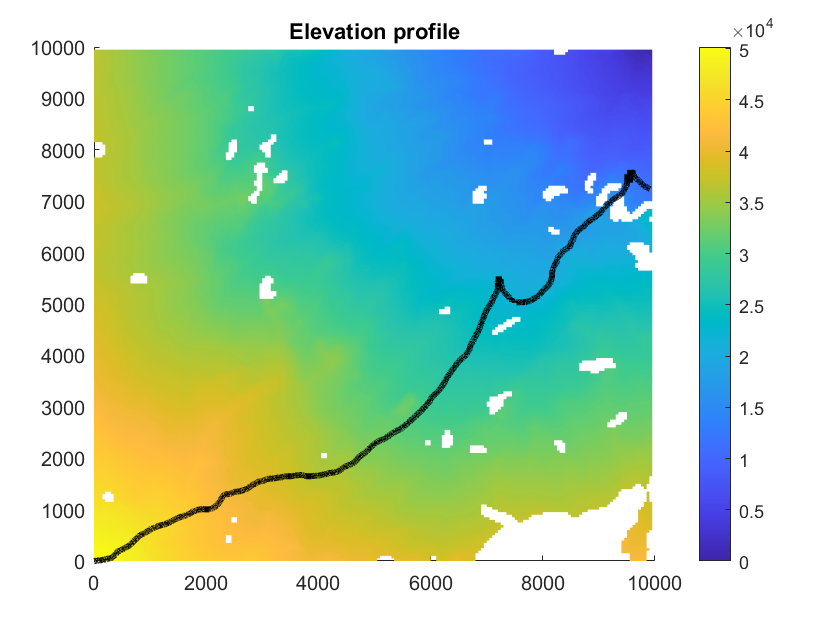

%clf(6);
figure(6);
hold on;
surf(XM, YM, costDP);
plot3(x_traj(1:num_u), y_traj(1:num_u), 1e5*ones(num_u,1), 'k', 'LineWidth',3);
title("Elevation profile");
shading interp;
colorbar;
hold off;

%clf(7);
figure(7);
hold on;
yp_min = 1602;
yp_max = 1635;
xp_min = 3180;
xp_max = 3220;
surf(Xm(yp_min:yp_max,xp_min:xp_max), Ym(yp_min:yp_max,xp_min:xp_max), costDPm(yp_min:yp_max,xp_min:xp_max));
x_traj_i = find(3199 - x_traj < 2, 1);
y_traj_i = find(1619 - y_traj < 2, 1);
plot3(x_traj(x_traj_i-20:x_traj_i+23), y_traj(y_traj_i-20:y_traj_i+23), 1e5*ones(44,1), 'k', 'LineWidth',3);
plot3(Xm(1619,3199), Ym(1619,3199), 1e5, 'rx', 'MarkerSize',10, 'LineWidth',2);
[~] = plotCircle(Xm(1619,3199), Ym(1619,3199), 3)
xlim([xp_min,xp_max]);
ylim([yp_min,yp_max]);
title("Obstacle Avoidance");
shading interp;
hold off;

function h = plotCircle(x,y,r)
    hold on
    th = 0:pi/50:2*pi;
    xunit = r * cos(th) + x;
    yunit = r * sin(th) + y;
    h = plot3(xunit, yunit, 1e5*ones(size(xunit)), 'r', 'LineWidth',2);
    hold off
end

## MPC Cost Function

function J = mpcCostFunction(u)
global x_start y_start;
global x_min y_min x_max y_max;
global Xm Ym;
global Zm soilm obsm vism costDPm;
global w1 w2 w3 w4 w5;
global Np;
global num_u;

    % vectors to store resultant x & y trajectories using control seq u
    x = zeros(Np+1,1);
    y = zeros(Np+1,1);

    % Initialize x and y
    x(1) = x_start;
    y(1) = y_start;

%     ob_i = [];      % Indices of out-of-bound x or y
    for i=1:Np
        % Calculating the next x & y (at k+1) 
        tau = (x(i) - x_start)*cos(u(i)) + (y(i) - y_start)*sin(u(i));
        delta_s = sqrt((2*(i-1)+1) + (tau^2)) - tau;    % k starts from 0 in this formula
        x(i+1) = x(i) + delta_s*cos(u(i));
        y(i+1) = y(i) + delta_s*sin(u(i));

        % Checking for x(i+1) and y(i+1) to be within bounds
        if (x(i+1) < x_min || x(i+1) > x_max) || (y(i+1) < y_min || y(i+1) > y_max)
            J = inf;
            return;
%             ob_i = [ob_i; i+1];
        end
    end

    % Penalizing out-of-bound occurences
%     if length(ob_i) ~= 0
%         J = 0;
%         for i=1:length(ob_i)
%             % x coordinate out-of-bound
%             if x(i+1) < x_min
%                 J = J + ((1e10 - 1e6)/Np)*abs(x(i+1) - x_min);
%             elseif x(i+1) > x_max
%                 J = J + ((1e10 - 1e6)/Np)*abs(x(i+1) - x_max);
%             end
%             % y coordinate out-of-bound
%             if y(i+1) < y_min
%                 J = J + ((1e10 - 1e6)/Np)*abs(y(i+1) - y_min);
%             elseif y(i+1) > y_max
%                 J = J + ((1e10 - 1e6)/Np)*abs(y(i+1) - y_max);
%             end
%         end
%         return;
%     end

    % Calculating the z profile
    z = Zm(sub2ind(size(Zm), round(x)+1, round(y)+1));  % Interpolation was very expensive

    % Distance cost
    J_dist = sum(sqrt((x(2:end)- x(1:end-1)).^2 + (y(2:end)- y(1:end-1)).^2 + (z(2:end)- z(1:end-1)).^2));

    % Soil cost
    soil_r = soilm(sub2ind(size(soilm), round(x)+1, round(y)+1));  % Soil rating (interpolation was very expensive)
    soil_r = ones(size(soil_r))./soil_r;
    J_soil = sum(soil_r(2:end) + soil_r(1:end-1));

    % Elevation cost
    J_elev = sum(abs(z(2:end) - z(1:end-1)));

    % Obstacle cost
    check_y_min = max(round(y_start)-Np+1, y_min+1);
    check_y_max = min(round(y_start)+Np+1, y_max+1);
    check_x_min = max(round(x_start)-Np+1, x_min+1);
    check_x_max = min(round(x_start)+Np+1, x_max+1);
    obs_i = find(obsm(check_y_min:check_y_max, check_x_min:check_x_max));
    J_obs = 0;
    if length(obs_i >= 1)
        sub_obsm = obsm(check_y_min:check_y_max, check_x_min:check_x_max);
        [ro,co] = ind2sub(size(sub_obsm),obs_i);
        ro = check_y_min + ro - 1;
        co = check_x_min + co - 1;
        x_obs = Xm(ro,co);
        y_obs = Ym(ro,co);

        hit_obs = (((x-x_obs).^2 + (y-y_obs).^2 - 3^2) <= 1);
        hit_obs = sum(hit_obs);
        J_obs = w4*hit_obs;
    end

    % Visibility cost
    J_vis = sum(vism(sub2ind(size(vism), round(x(2:end))+1, round(y(2:end))+1)));
    
    % Terminal cost
    J_dp = costDPm(sub2ind(size(costDPm), round(x(end))+1, round(y(end))+1));

    % Sum of local costs
    J_local = w1*J_dist + w2*J_soil + w3*J_elev + w5*J_vis;

    % Scaling factor
    scaleF = 0.1*J_dp/J_local;

    % Total MPC cost
    J = scaleF*J_local + J_dp + 10*scaleF*w4*J_obs;
end